初期状態の値(initial_generator_state)と状態定常値の差に関して、定常値に収束するための初期値誤差を調べ、その境界を探索する 

状態における誤差は　10^left　10^right  とおく  ( 例、left = -17 のとき 10^-17 ) 

( left: 最終状態値と状態定常値との差がゼロであるべき指数,  right: 最終状態値と状態定常値との差がゼロではない指数 )

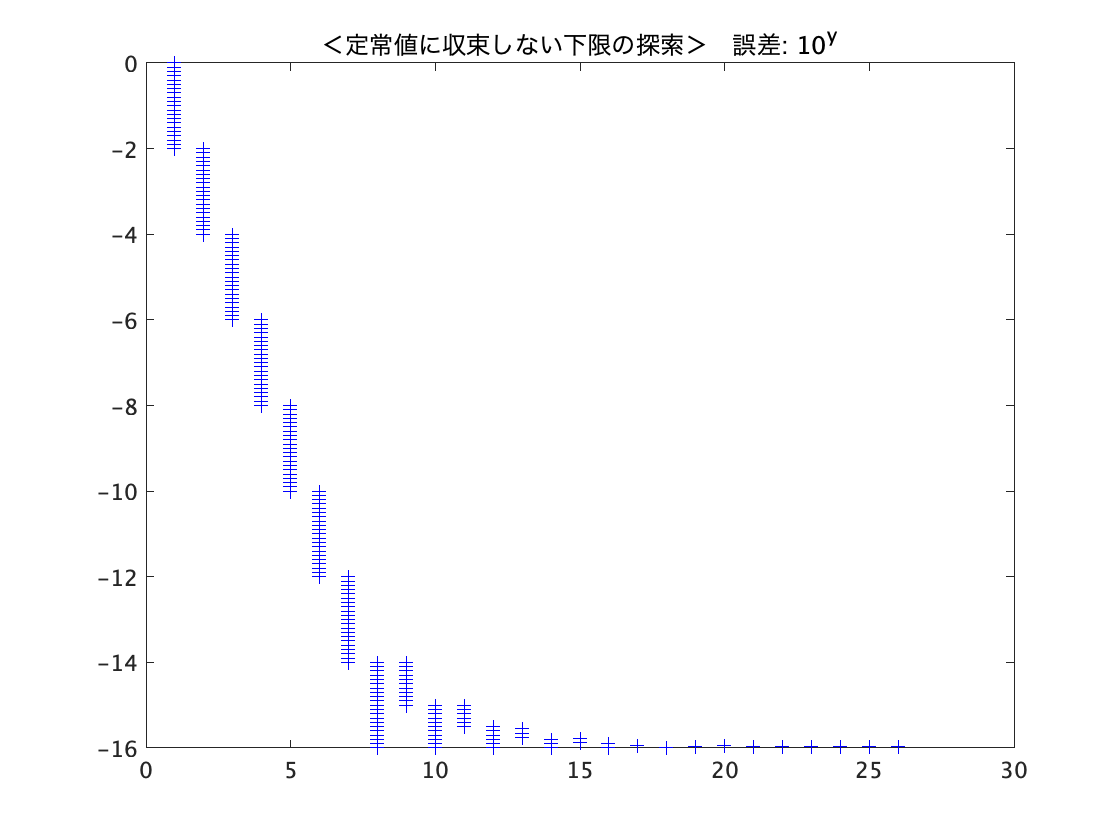

ans =     -2     0


ans = 1.7069e+05

ans =     -4    -2


ans = 11.0053

ans =     -6    -4


ans = 3.6285e+04

ans =     -8    -6


ans = 3.6239e+04

ans =    -10    -8


ans = 3.6145e+04

ans =    -12   -10


ans = 3.5984e+04

ans =    -14   -12


ans = 3.5805e+04

ans =    -16   -14


ans = 3.5596e+04

ans =    -15   -14


ans = 3.4856e+04

ans =    -16   -15


ans = 3.4856e+04

ans =   -15.5000  -15.0000


ans = 3.3884e+04

ans =   -16.0000  -15.5000


ans = 3.3884e+04

ans =   -15.7500  -15.5000


ans = 3.4096e+04

ans =   -16.0000  -15.7500


ans = 3.4096e+04

ans =   -15.8750  -15.7500


ans = 1.5960e+05

ans =   -16.0000  -15.8750


ans = 1.5960e+05

ans =   -15.9375  -15.8750


ans = 1.5960e+05

ans =   -16.0000  -15.9375


ans = 1.5960e+05

ans =   -15.9688  -15.9375


ans = 1.5960e+05

ans =   -15.9531  -15.9375


ans = 1.5960e+05

ans =   -15.9688  -15.9531


ans = 1.5960e+05

ans =   -15.9609  -15.9531


ans = 1.5960e+05

ans =   -15.9570  -15.9531


ans = 1.5960e+05

ans =   -15.9551  -15.9531


ans = 1.5960e+05

ans =   -15.9541  -15.9531


ans = 1.5960e+05

ans =   -15.9551  -15.9541


ans = 1.5960e+05

ans = 4

clear
left = 0;
right = 2;

tspan = [0 100];

%定常値を設定
steady_delta = [1;3;5];
steady_E = [1;3;2];
steady_deltaomega = [0;0;0];
steady_generator_state = [steady_delta; steady_E; steady_deltaomega];



%最終時間における状態値と状態定常値の差を得る
get_final_error_wrap = @(error) get_final_error(error,tspan, steady_generator_state);

error_left = get_final_error_wrap(left);
error_right = get_final_error_wrap(right);

t = 1;
f1 = figure;
f2 = figure;

% max(abs(error_right(:))) > ?????　でどれだけの誤差まで許容するかを設定（max(初期値)<1なら0.000001程度、max(初期値)>1なら1）
% t < ???? で最高何回探索するかを設定
while (max(abs(error_right(:))) > 1 | all(error_right(:)) == 0 ) & t < 30
    
    if all(error_left(:)) == 0 & any(error_right(:)) ~= 0
        
        %1
        if (right - left) < 0.001
            4
            break
        end
        
        left = (right + left) /2;
        

        
    elseif  all(error_right(:)) == 0
        
        %2
        
        temp = left;
        
        left = right;
        
        right = right + (right - temp);
        
    elseif any(error_left(:)) ~= 0
        
        %3
        
        temp = right;
        
        right = left;
        
        left = left - (temp - right);
      
    end
    [left, right]
    max(abs(error_right(:)))
    figure(f1);
    plot(t,left:0.1:right,'b+')
    title('＜定常値に収束しない下限の探索＞　誤差: 10^y')
    hold on
    
    if max(abs(error_right(:))) > 0
        figure(f2);
        plot(t,max(abs(error_right(:))),'r*')
        title('定常値との最大誤差の絶対値')
        hold on
    end
    
    t = t + 1;
    
    error_left = get_final_error_wrap(left);
    error_right = get_final_error_wrap(right);

end

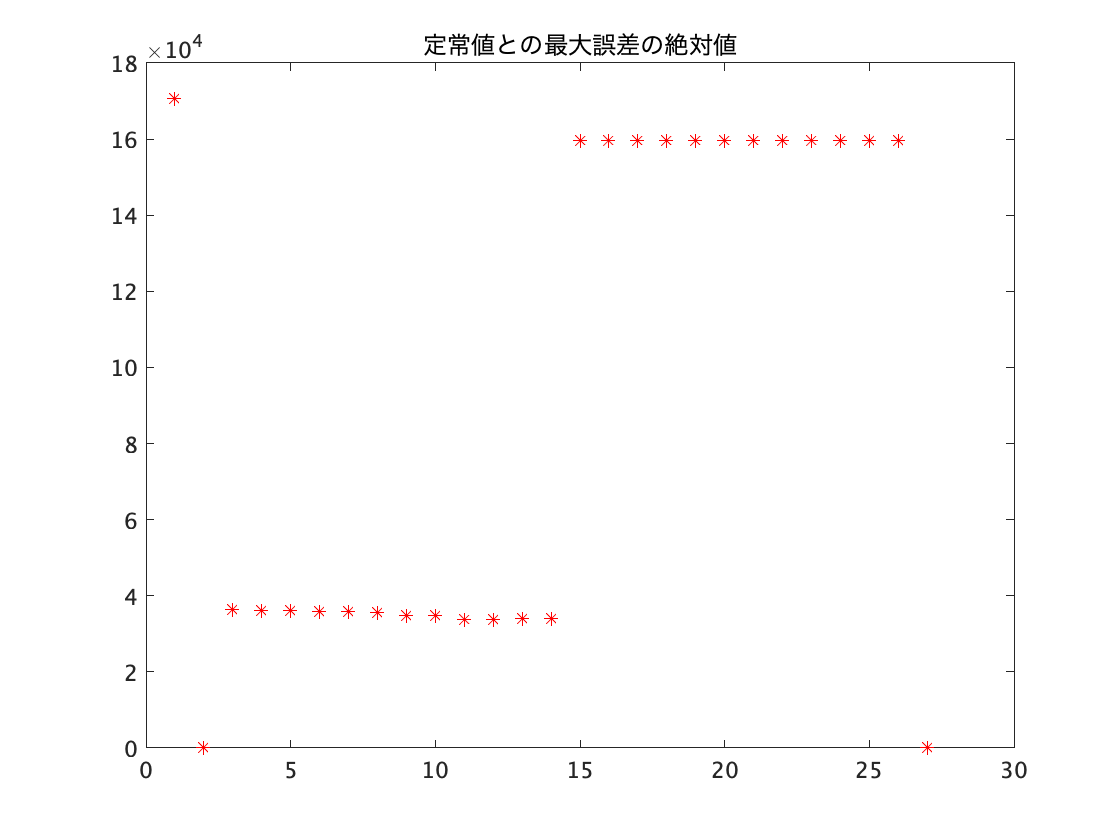

figure(f2);
plot(t,max(abs(error_left(:))),'r*')
hold off

right

right = -15.9541

left

left = -15.9551

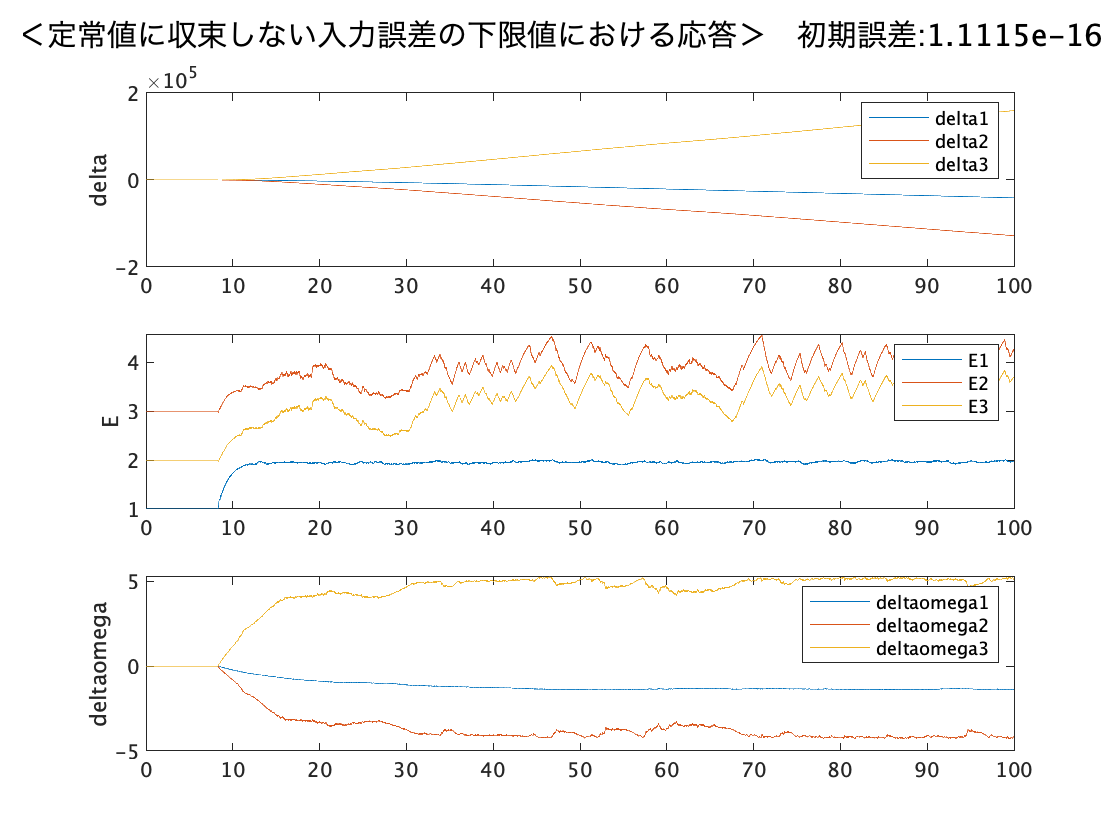

figure;
plot_generator_state(right,tspan,steady_generator_state)
sgtitle(['＜定常値に収束しない入力誤差の下限値における応答＞　初期誤差:',num2str(10^right)])

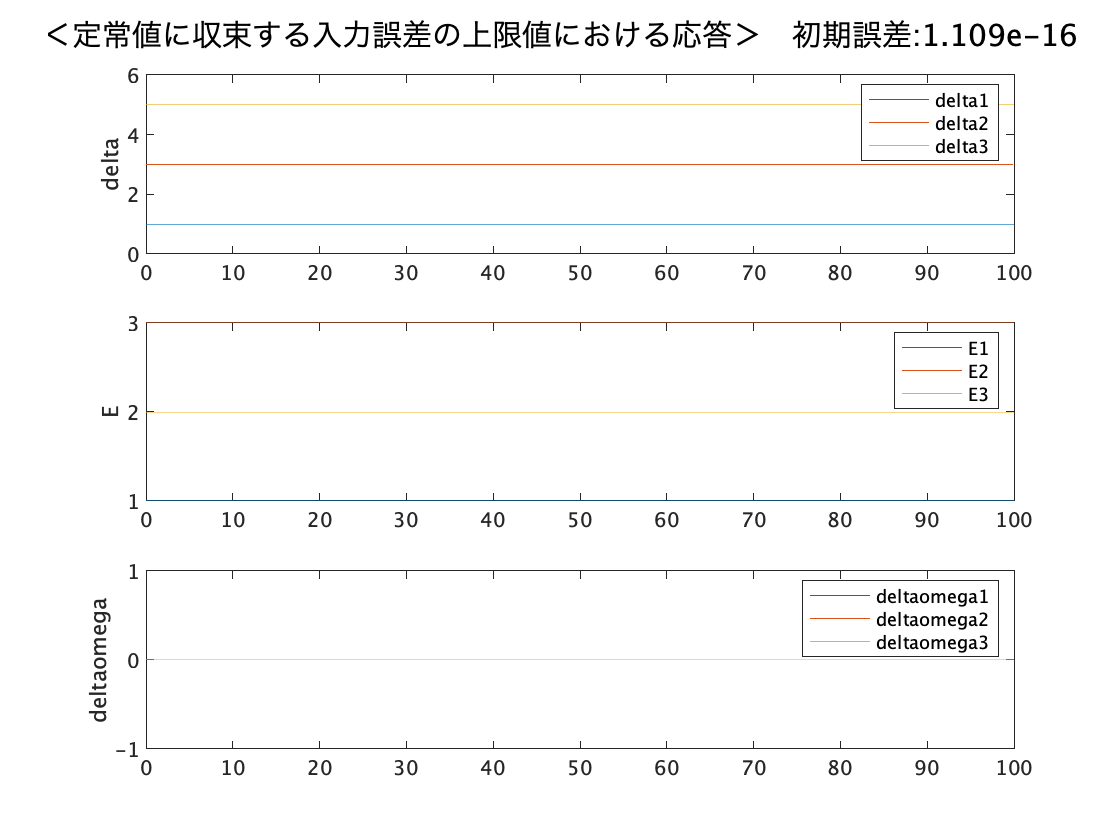

figure;
plot_generator_state(left,tspan,steady_generator_state)
sgtitle(['＜定常値に収束する入力誤差の上限値における応答＞　初期誤差:',num2str(10^left)])